EE 451 Homework 6

Lisa Jacklin

%problem 2
%part a
N = 4; %given
%just so its easy for me to use, rather than i1, I will create j
j = sqrt(-1);

xn = [1 2 3 1]; %values given for x(n)
%from this, we can use the dftfunction we built in class to determine the
%Xk which can be converted back to xn using idft which will be graphed
%below.
Xk = fft(xn, N);
stem(Xk); %note that only the real parts are used

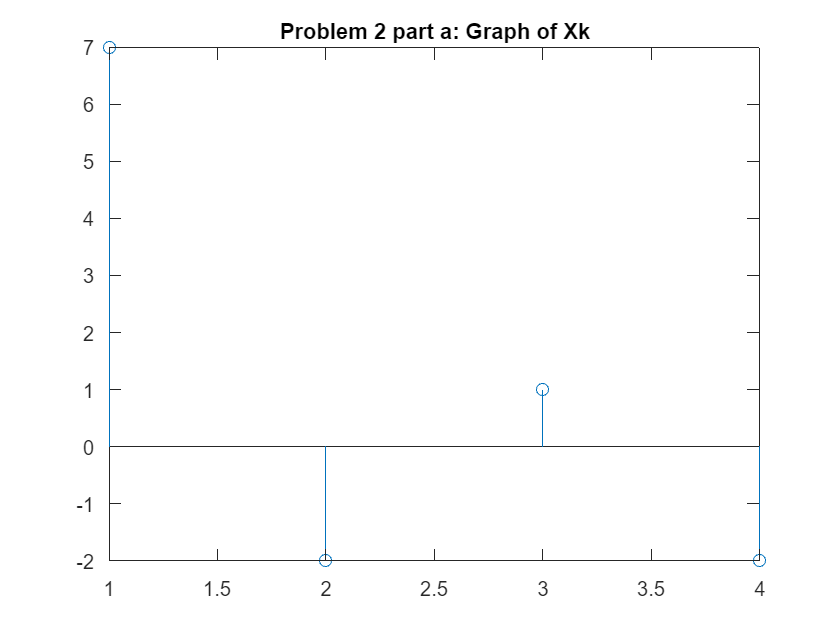

title("Problem 2 part a: Graph of Xk");

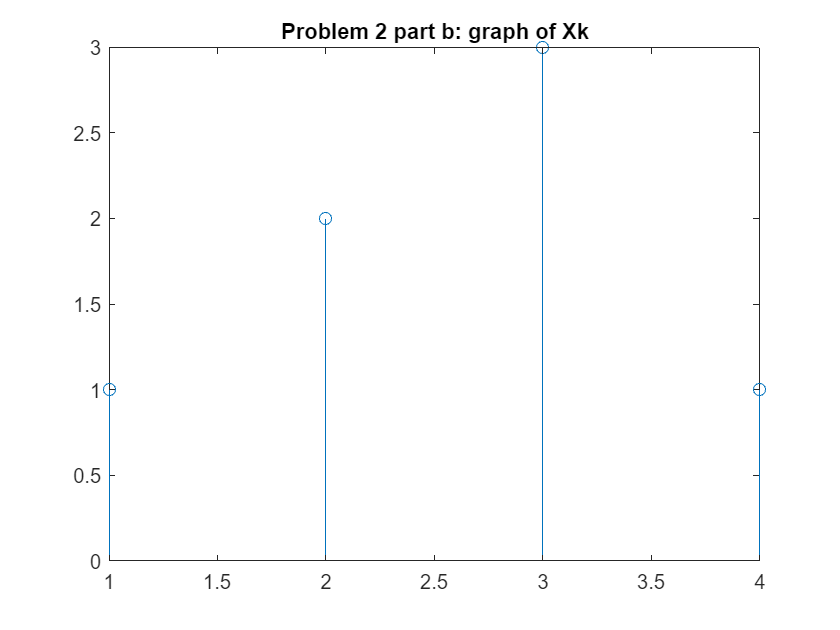

%Problem 2 part b

Xk2 = dft(xn, N);
stem(xn);
title("Problem 2 part b: graph of Xk");

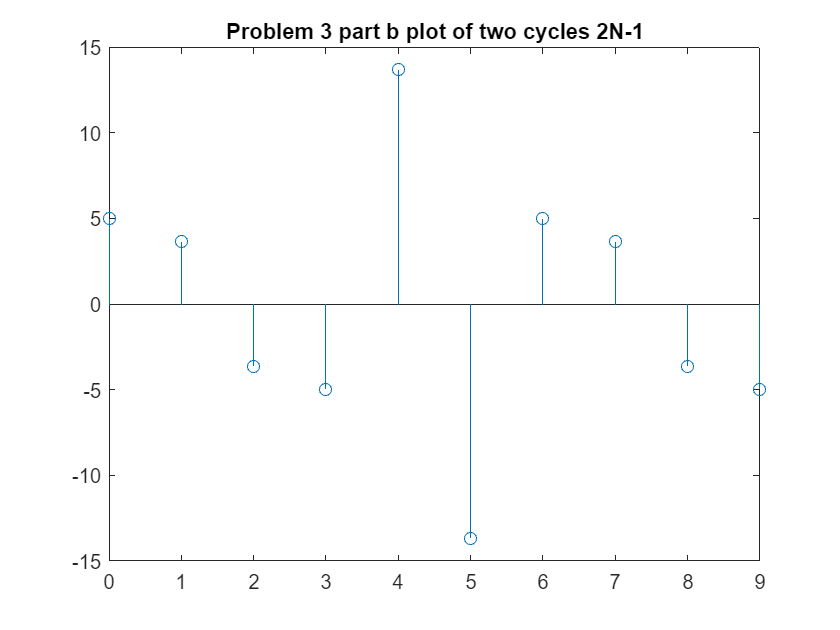


%Problem 3
%we are given the periodic equation x(n) = 5*cos(pi*n) + 10*sin((2*pi*n)/3)
%before we can do anything, we need to determine the period N of this
%function.

%problem 3 part a: What is N?
%since we are messing with cos and sin, an since sin has an admustment of
%2pi/3,but there is no adjustment to cos and since they are added together, we get 7pi/4ths....
N = 7*pi/4;

%with the value of N determined, we can finally begin to consider more
%about x(n).

%problem 3 part b: plot the signal for two cycles.
n = 0:1:2*N-1;
xpn = 5*cos(pi*n) + 10*sin((2*pi*n)/3);

stem(n, xpn);
title("Problem 3 part b plot of two cycles 2N-1")


%problem 3 part c: now we need to split x(n) into two sections to be
%considered, x1(n) which is over a single cycle and x2(n) which is
%considered over two cycles.

%note that x1n and x2n are both equal to xpn but are tested over separate
%intervals.
n1 = 0:1:N-1;
x1n = 5*cos(pi*n1) + 10*sin((2*pi*n1)/3);

n2 = 0:1:2*N-1;
x2n = 5*cos(pi*n2) + 10*sin((2*pi*n2)/3);
%once this is determined and plotted in terms of magnitude and phase, the
%2n point dft of x1 and x2 are determined and plotted as well.

%Npt = 7*pi; %we need to determine the 2N point DFT for x1n and x2n.

%theoretically, using these two chunks which are the ame equation measured
%at different period lengths, over 2N of the value should produce the
%correct X(k) values we are looking for in both.
%X1k = dft(x1n, 2*N);
%X2k = dft(xpn, 2*N);

%then, once this is determined, we would need to plot the magnitude and
%phase of each of the equations which can be done by performing
%plot(abs(X(k)) on each to get the magnitude, and performing an fft on each
%and doing the same to obtain the phase.....

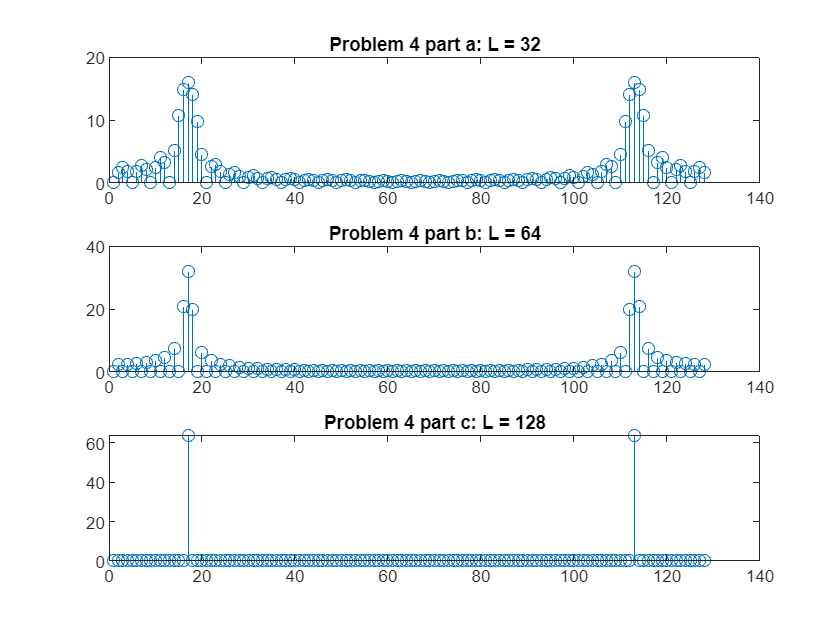

%Problem 4

Fs = 16; %16 Hz sampling frequency
Ts = 1/Fs; %sampling time

%ft = sin(4*pi*t); 
%given function that will be tested. note that this needs to be converted
%into discrete function when we continue on.

%make noet that for this problem, since N is the sampling rate and we know
%that we need N>= L, for the case of this problem,N = L since we are given
%the length of the functions.

%also note that within the problem it is specified that we need a total of
%128 points in all dft calculations.

%part a: L = 32
La = 32;
na = 0:1:La-1;
fna = sin(4*pi*na*Ts);

Xka = dft(fna, 128);
subplot(3, 1, 1);
stem(abs(Xka));
title("Problem 4 part a: L = 32");

%part b: L = 64
Lb = 64;
nb = 0:1:Lb-1;
fnb = sin(4*pi*nb*Ts);

Xkb = dft(fnb, 128);
subplot(3, 1, 2);
stem(abs(Xkb));
title("Problem 4 part b: L = 64");

%part c: L = 128
Lc = 128;
nc = 0:1:Lc-1;
fnc = sin(4*pi*nc*Ts);

Xkc = dft(fnc, 128);
subplot(3, 1, 3);
stem(abs(Xkc));
title("Problem 4 part c: L = 128");

%Part d: comment on the results obtained.

%as can be seen by comparing the three stem plots above, it can be seen
%that the less zero padding required to obtain the desired dft of 128, the
%more precise each graph becomes. The closer the length gets to the
%sampling values, less noise is shown until we obtain the exact frequency
%at which we are obtaining as well as a more acurate amplitude at said
%frequency.
